# Local Minimum Test

Starting wave glider path planning...
Goal reached in 5650 iterations!

Wave Glider Path Statistics:
  Path length: 121.15 m
  Total time: 378.8 s (6.3 min)
  Average ground speed: 0.32 m/s
  Waypoints: 1894
  Total turning: 35.63 rad (2041.3 deg)

--- Computation Performance ---
Total computation time: 0.1777 seconds

--- Wave Glider Parameters ---
Average Speed: 0.32 m/s
Turning Radius: 0.98 m
Max Turn Rate: 0.327 rad/s (18.7 deg/s)


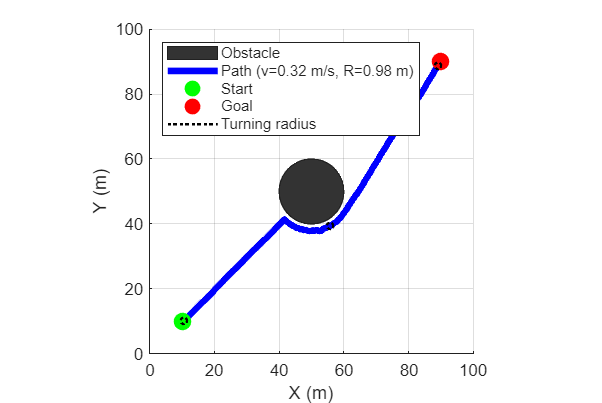

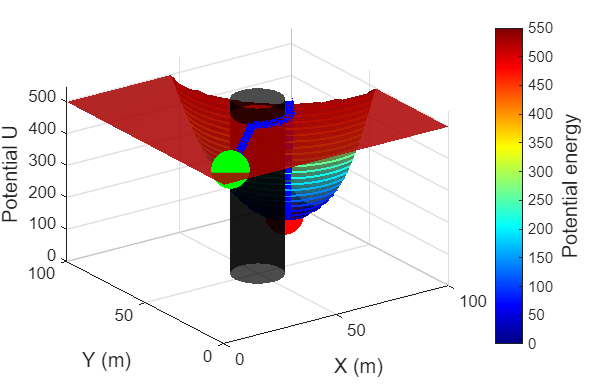

function apf_local_minimum()
    % Artificial Potential Field Method for Local Path Planning
    % With Wave Glider Dynamics
    % Local Minimum Test

    % Clear workspace
    clear; close all; clc;

    % Environment setup
    field_size = 100;     % Size of the field (100m x 100m)
    resolution = 2;     % Grid resolution (coarser for larger field)
    x = 0:resolution:field_size;
    y = 0:resolution:field_size;
    [X, Y] = meshgrid(x, y);

    % Robot parameters
    start_pos   = [10, 10];     % Starting position
    goal_pos    = [90, 90];     % Goal position
    robot_radius = 2;         % Robot radius for collision detection

    % Wave Glider Parameters
    wave_glider.avg_speed = 0.32;        % Average speed (m/s)
    wave_glider.turning_radius = 0.98;   % Minimum turning radius (m)
    wave_glider.max_turn_rate = wave_glider.avg_speed / wave_glider.turning_radius; % rad/s

    % Obstacle
    obstacles = [50, 50, 10;];

    % APF parameters
    k_att = 0.5;        % Attractive force gain
    k_rep = 15;       % Repulsive force gain
    d0    = 20;       % Influence distance of obstacles
    dt    = 0.2;        % Time step for wave glider dynamics (s)
    max_iterations = 10000; 

    % Environmental current parameters
    k_env = 2;        % Weight of environmental influence

    % CREATE COMPLEX EDDY CURRENT FIELD (not used in this example)
    [Ux, Uy] = create_eddy_current_field(X, Y);

    % Calculate potentials
    U_att   = attractive_potential(X, Y, goal_pos, k_att);
    U_rep   = repulsive_potential(X, Y, obstacles, k_rep, d0);
    U_env   = environmental_potential(X, Y, Ux, Uy, k_env);
    U_total = U_att + U_rep + U_env;

    % Path planning with wave glider dynamics
    tic;
    path_with_dynamics = path_planning_wave_glider(start_pos, goal_pos, obstacles, ...
        k_att, k_rep, d0, dt, max_iterations, robot_radius, k_env, Ux, Uy, wave_glider);
    computation_time = toc;

    fprintf('\n--- Computation Performance ---\n');
    fprintf('Total computation time: %.4f seconds\n', computation_time);

    % Display wave glider parameters
    fprintf('\n--- Wave Glider Parameters ---\n');
    fprintf('Average Speed: %.2f m/s\n', wave_glider.avg_speed);
    fprintf('Turning Radius: %.2f m\n', wave_glider.turning_radius);
    fprintf('Max Turn Rate: %.3f rad/s (%.1f deg/s)\n', wave_glider.max_turn_rate, rad2deg(wave_glider.max_turn_rate));

    % Visualization
    visualize_results(X, Y, U_total, start_pos, goal_pos, ...
        obstacles, path_with_dynamics, field_size, Ux, Uy, wave_glider);
    
    % 3D Potential Field Visualization
    visualize_3d_potential(X, Y, U_total, start_pos, goal_pos, ...
        obstacles, path_with_dynamics, field_size);
end

%% Eddy current field generation
function [U, V] = create_eddy_current_field(X, Y)
    % Create simple zero current field
    U = zeros(size(X));
    V = zeros(size(Y));
end

%% Wave Glider Path Planning
function path = path_planning_wave_glider(start_pos, goal_pos, obstacles, ...
    k_att, k_rep, d0, dt, max_iter, robot_radius, k_env, Ux, Uy, wave_glider)

    % Local-minima escape parameters
    stagnation_window     = 70;      % steps to look back for progress
    min_improve           = 0.5;     % m of improvement required over the window
    force_eps             = 0.05;    % N-ish threshold: "gradient nearly zero"
    escape_angle_deg      = 85;      % rotate APF force by this angle during escape
    escape_duration_sec   = 1;     % seconds to keep escaping
    escape_steps_default  = max(1, round(escape_duration_sec / dt));

    % State
    current_pos     = start_pos;
    current_heading = 0;                         % rad
    current_speed   = wave_glider.avg_speed;     % m/s
    goal_threshold  = 1;                       % m

    path     = current_pos;
    headings = current_heading;

    % Progress tracking
    dist_hist = [];
    best_dist_recent = inf;
    no_improve_steps = 0;

    % Escape mode state
    escape_steps_left = 0;
    escape_sign       = 1;  % +1 or -1
    escape_angle_rad  = deg2rad(escape_angle_deg);

    fprintf('Starting wave glider path planning...\n');

    for iter = 1:max_iter
        % Interpolate current
        c = get_current_at_position(current_pos, Ux, Uy);

        % Compute APF force at the current position
        [Fx, Fy] = calculate_forces(current_pos, goal_pos, obstacles, ...
                                    k_att, k_rep, d0, k_env, c);

        % Local-minima prevention: decide if should enter escape mode
        dist_to_goal = norm(current_pos - goal_pos);

        % Track recent progress
        dist_hist = [dist_hist; dist_to_goal]; %#ok<AGROW>
        if numel(dist_hist) > stagnation_window
            recent = dist_hist(end-stagnation_window+1:end);
            best_recent = min(recent);
            % If not clearly beating the recent best OR the force is tiny, consider "stuck"
            if (best_dist_recent - dist_to_goal) < min_improve
                no_improve_steps = no_improve_steps + 1;
            else
                no_improve_steps = 0;
            end
            best_dist_recent = min(best_dist_recent, dist_to_goal);

            if (no_improve_steps >= stagnation_window) || (hypot(Fx, Fy) < force_eps)
                % Start/refresh a short escape where bias the force sideways
                escape_sign       = sign(randn); % random left/right
                if escape_sign == 0, escape_sign = 1; end
                escape_steps_left = escape_steps_default;
                no_improve_steps  = 0;  % reset the counter
            end
        else
            % Initialise the reference as the best seen so far
            best_dist_recent = min(best_dist_recent, dist_to_goal);
        end

        % If escaping, rotate the APF force by ±escape_angle
        if escape_steps_left > 0
            [Fx, Fy] = rotate_vec(Fx, Fy, escape_sign * escape_angle_rad);
            escape_steps_left = escape_steps_left - 1;
        end

        % Desired heading from (possibly rotated) force
        desired_heading = atan2(Fy, Fx);

        % Heading change limited by turn-rate (turning-radius) constraint
        heading_error = atan2(sin(desired_heading - current_heading), ...
                              cos(desired_heading - current_heading));
        max_heading_change = wave_glider.max_turn_rate * dt;
        if abs(heading_error) > max_heading_change
            current_heading = current_heading + sign(heading_error) * max_heading_change;
        else
            current_heading = desired_heading;
        end
        % Wrap
        current_heading = atan2(sin(current_heading), cos(current_heading));

        % Body -> ground velocity (add current)
        vx_body   = current_speed * cos(current_heading);
        vy_body   = current_speed * sin(current_heading);
        vx_ground = vx_body + c(1);
        vy_ground = vy_body + c(2);

        % Integrate position
        next_pos = current_pos + dt * [vx_ground, vy_ground];

        % Boundary check
        if next_pos(1) < 0 || next_pos(1) > 100 || next_pos(2) < 0 || next_pos(2) > 100
            fprintf('Boundary reached at iter %d, stopping\n', iter);
            break;
        end

        % Collision check
        collision = false;
        for i = 1:size(obstacles, 1)
            oc = obstacles(i, 1:2); orad = obstacles(i, 3);
            if norm(next_pos - oc) < (orad + robot_radius)
                collision = true; 
                break;
            end
        end

        if ~collision
            current_pos = next_pos;
            path     = [path; current_pos];     %#ok<AGROW>
            headings = [headings; current_heading]; %#ok<AGROW>
        else
            % Simple "try left/right once" fallback
            for turn_sign = [-1, 1]
                test_heading = current_heading + turn_sign * max_heading_change;
                test_vx = current_speed * cos(test_heading) + c(1);
                test_vy = current_speed * sin(test_heading) + c(2);
                test_pos = current_pos + dt * [test_vx, test_vy];
                test_collision = false;
                for k = 1:size(obstacles, 1)
                    oc = obstacles(k, 1:2); orad = obstacles(k, 3);
                    if norm(test_pos - oc) < (orad + robot_radius)
                        test_collision = true;
                        break;
                    end
                end
                if ~test_collision
                    current_heading = test_heading;
                    current_pos     = test_pos;
                    path     = [path; current_pos];     %#ok<AGROW>
                    headings = [headings; current_heading]; %#ok<AGROW>
                    break;
                end
            end
            % If collided, also nudge escape mode so don't get re-trapped
            if collision
                escape_sign       = sign(randn); if escape_sign==0, escape_sign=1; end
                escape_steps_left = escape_steps_default;
            end
        end

        % Goal check
        if norm(current_pos - goal_pos) < goal_threshold
            fprintf('Goal reached in %d iterations!\n', iter);
            break;
        end

    end

    if iter == max_iter
        fprintf('Maximum iterations reached.\n');
    end

    % Stats
    if size(path, 1) > 1
        path_length = sum(vecnorm(diff(path), 2, 2));
        total_time = size(path, 1) * dt;
        avg_ground_speed = path_length / total_time;
        fprintf('\nWave Glider Path Statistics:\n');
        fprintf('  Path length: %.2f m\n', path_length);
        fprintf('  Total time: %.1f s (%.1f min)\n', total_time, total_time/60);
        fprintf('  Average ground speed: %.2f m/s\n', avg_ground_speed);
        fprintf('  Waypoints: %d\n', size(path,1));
        if length(headings) > 1
            dhead = diff(headings);
            dhead = atan2(sin(dhead), cos(dhead));
            total_turning = sum(abs(dhead));
            fprintf('  Total turning: %.2f rad (%.1f deg)\n', total_turning, rad2deg(total_turning));
        end
    end
end

function [rx, ry] = rotate_vec(x, y, ang)
    % Rotate a 2D vector by angle 'ang' (radians)
    ca = cos(ang); sa = sin(ang);
    rx = ca*x - sa*y;
    ry = sa*x + ca*y;
end


%% Helper Functions
function c = get_current_at_position(pos, Ux, Uy)
    % Interpolate current field at given position
    % Simple nearest neighbor for now
    x_idx = max(1, min(size(Ux, 2), round(pos(1)/2) + 1));
    y_idx = max(1, min(size(Ux, 1), round(pos(2)/2) + 1));
    c = [Ux(y_idx, x_idx), Uy(y_idx, x_idx)];
end

function diff = angle_diff(angle1, angle2)
    % Calculate the shortest angular difference between two angles
    diff = angle1 - angle2;
    diff = atan2(sin(diff), cos(diff)); % Wrap to [-pi, pi]
end

%% Potential Functions 
function U_att = attractive_potential(X, Y, goal, k_att)
    U_att = k_att * ((X - goal(1)).^2 + (Y - goal(2)).^2) / 2;
end

function U_rep = repulsive_potential(X, Y, obstacles, k_rep, d0)
    U_rep = zeros(size(X));
    for i = 1:size(obstacles, 1)
        obs_x = obstacles(i, 1);
        obs_y = obstacles(i, 2);
        obs_r = obstacles(i, 3);

        % Distance to obstacle surface
        d_obs = sqrt((X - obs_x).^2 + (Y - obs_y).^2) - obs_r;

        % Inside obstacle
        inside_mask = d_obs <= 0;
        d_obs(inside_mask) = eps;

        % Within influence range
        mask = (d_obs > 0) & (d_obs <= d0);
        U_rep(mask) = U_rep(mask) + 0.5 * k_rep * ((1./d_obs(mask)) - (1/d0)).^2;

        % High potential inside obstacles
        U_rep(inside_mask) = 1000;
    end
end

function U_env = environmental_potential(X, Y, Ux, Uy, k_env)
    % Linear potential whose negative gradient gives current force
    U_env = -k_env * (Ux .* X + Uy .* Y);
end

%% Force Calculation 
function [F_x, F_y] = calculate_forces(pos, goal, obstacles, k_att, k_rep, d0, k_env, c)
    % Attractive force
    x = pos(1); y = pos(2);
    F_att_x = -k_att * (x - goal(1));
    F_att_y = -k_att * (y - goal(2));

    % Repulsive forces
    F_rep_x = 0; F_rep_y = 0;
    for i = 1:size(obstacles, 1)
        ox = obstacles(i, 1); oy = obstacles(i, 2); orad = obstacles(i, 3);
        d_center = sqrt((x - ox)^2 + (y - oy)^2);
        d_obs = d_center - orad;

        if d_obs > 0 && d_obs <= d0
            % Unit vector from obstacle center to robot
            ux = (x - ox) / max(d_center, eps);
            uy = (y - oy) / max(d_center, eps);

            F_rep_mag = k_rep * (1/d_obs - 1/d0) * (1/d_obs^2);
            F_rep_x = F_rep_x + F_rep_mag * ux;
            F_rep_y = F_rep_y + F_rep_mag * uy;

        elseif d_obs <= 0
            % Strong push out if inside
            ux = (x - ox) / max(d_center, eps);
            uy = (y - oy) / max(d_center, eps);
            F_rep_x = F_rep_x + 100 * ux;
            F_rep_y = F_rep_y + 100 * uy;
        end
    end

    % Environmental (current) force
    F_env_x = k_env * c(1);
    F_env_y = k_env * c(2);

    % Total force
    F_x = F_att_x + F_rep_x + F_env_x;
    F_y = F_att_y + F_rep_y + F_env_y;
end

%% 2D Path Visualization
function visualize_results(X, Y, U_total, start_pos, goal_pos, ...
    obstacles, path, field_size, Ux, Uy, wave_glider)

    figure('Position', [100, 100, 1200, 800]);
    
    hold on;
    
    % Draw obstacles
    for i = 1:size(obstacles, 1)
        cx = obstacles(i,1); cy = obstacles(i,2); cr = obstacles(i,3);
        th = linspace(0, 2*pi, 100);
        xf = cx + cr*cos(th); yf = cy + cr*sin(th);
        if i == 1
            fill(xf, yf, 'k', 'FaceAlpha', 0.8, 'DisplayName', 'Obstacle');
        else
            fill(xf, yf, 'k', 'FaceAlpha', 0.8, 'HandleVisibility','off');
        end
    end
    
    % Plot wave glider path
    plot(path(:,1), path(:,2), 'b-', 'LineWidth', 4, ...
         'DisplayName', sprintf('Path (v=%.2f m/s, R=%.2f m)', ...
         wave_glider.avg_speed, wave_glider.turning_radius));
    
    % Start and goal points
    plot(start_pos(1), start_pos(2), 'go', 'MarkerSize', 10, ...
         'MarkerFaceColor','g', 'DisplayName','Start');
    plot(goal_pos(1), goal_pos(2), 'ro', 'MarkerSize', 10, ...
         'MarkerFaceColor','r', 'DisplayName','Goal');
    
    % Add some sample turning radius circles along the path
    if size(path, 1) > 20
        n_circles = 3;
        circle_indices = round(linspace(10, size(path, 1)-10, n_circles));
        
        for idx = circle_indices
            pos = path(idx, :);
            th = linspace(0, 2*pi, 50);
            circle_x = pos(1) + wave_glider.turning_radius * cos(th);
            circle_y = pos(2) + wave_glider.turning_radius * sin(th);
            if idx == circle_indices(1)
                plot(circle_x, circle_y, 'k:', 'LineWidth', 1.5, 'DisplayName', 'Turning radius');
            else
                plot(circle_x, circle_y, 'k:', 'LineWidth', 1.5, 'HandleVisibility', 'off');
            end
        end
    end
    
    xlabel('X (m)'); 
    ylabel('Y (m)');
    legend('show', 'Location', 'northwest');
    axis equal; 
    xlim([0, field_size]); 
    ylim([0, field_size]); 
    grid on;
    set(gca, 'YDir', 'normal');
end

%% 3D Potential Field Visualization
function visualize_3d_potential(X, Y, U_total, start_pos, goal_pos, ...
    obstacles, path, field_size)

    figure('Position', [100, 100, 1400, 900]);
    
    % Clip potential for better visualization
    U_clipped = U_total;
    U_clipped(U_clipped > 500) = 500;
    
    % Create surface plot
    surf(X, Y, U_clipped, 'EdgeColor', 'none', 'FaceAlpha', 0.85);
    hold on;
    
    % Add contour lines on the bottom
    contour3(X, Y, U_clipped, 20, 'LineWidth', 1.2);
    
    % Interpolate path z-values from potential field
    path_z = zeros(size(path, 1), 1);
    for i = 1:size(path, 1)
        % Find nearest grid point
        [~, x_idx] = min(abs(X(1,:) - path(i,1)));
        [~, y_idx] = min(abs(Y(:,1) - path(i,2)));
        path_z(i) = U_clipped(y_idx, x_idx);
    end
    
    % Plot the path on the surface
    plot3(path(:,1), path(:,2), path_z + 5, 'b-', 'LineWidth', 5);
    
    % Start and goal points
    start_z = interp2(X, Y, U_clipped, start_pos(1), start_pos(2));
    goal_z = interp2(X, Y, U_clipped, goal_pos(1), goal_pos(2));
    
    plot3(start_pos(1), start_pos(2), start_z + 5, 'go', ...
          'MarkerSize', 20, 'MarkerFaceColor', 'g', 'LineWidth', 3);
    plot3(goal_pos(1), goal_pos(2), goal_z + 5, 'ro', ...
          'MarkerSize', 20, 'MarkerFaceColor', 'r', 'LineWidth', 3);
    
    % Mark obstacles on surface
    for i = 1:size(obstacles, 1)
        cx = obstacles(i,1); cy = obstacles(i,2); cr = obstacles(i,3);
        obs_z = interp2(X, Y, U_clipped, cx, cy);
        
        % Draw cylinder for obstacle
        [Xcyl, Ycyl, Zcyl] = cylinder(cr, 50);
        Zcyl = Zcyl * (obs_z + 50);  % Height of cylinder
        mesh(Xcyl + cx, Ycyl + cy, Zcyl, 'FaceColor', 'k', ...
             'FaceAlpha', 0.7, 'EdgeColor', 'none');
    end
    
    % Styling
    colormap(jet);
    c = colorbar;
    c.Label.String = 'Potential energy';
    c.Label.FontSize = 12;
    
    xlabel('X (m)', 'FontSize', 12);
    ylabel('Y (m)', 'FontSize', 12);
    zlabel('Potential U', 'FontSize', 12);
    
    xlim([0, field_size]);
    ylim([0, field_size]);
    
    grid on;
    view(-35, 30);  % Good viewing angle
    
    % Lighting for better visualisation
    camlight('right');
    lighting gouraud;
    material shiny;
    
    % Make it interactive
    rotate3d on;
    
    hold off;
end

% Run the simulation
apf_local_minimum();